# Lab 1 Examples

Lab Instructor: Connor Robertson

## Example 1

Here are a few basic calculations and constructions that you will need to use throughout the course for building arrays of numbers. Take note of these constructions as they will be useful for the entire course

% a row vector, X=(0 1 2 3) can be written three ways:

% Here it is written using brackets:
X=[0 1 2 3]

X =      0     1     2     3



% including ; at the end of the line will suppress the output (it will
% still do the command but not print the variable:
X=[0 1 2 3];

% Here it is written in the form X=linspace(a,b,n) where
% a is the first point, b is the last and n is the number
% of equally spaced points
X=linspace(0, 3, 4)

X =      0     1     2     3



% linspace is a function that Matlab includes by default (it is in the
% Matlab standard library)

% Here it is written in the form X=a:delta:b where
% a is the first point, b is the last and delta is the 
% distance between each point
X=0:1:3

X =      0     1     2     3


% or just
X=0:3

X =      0     1     2     3



% Apply an operation to a whole array
% For example Y=[e^0, e^1, e^2, e^3]
Y=exp(X)

Y =     1.0000    2.7183    7.3891   20.0855


% exp is the matlab function for exponential

% or S=[sin(0), sin(1), sin(2), sin(3)]
S=sin(X)

S =          0    0.8415    0.9093    0.1411



% To make an array Q that contains the square root of each element in the 
% array X, type:
Q=sqrt(X)

Q =          0    1.0000    1.4142    1.7321



% A 2x2 identity matrix
Id=[1 0; 0 1]

Id =      1     0
     0     1


% note that the ; in the array definition marks the end of a row

% This can also be written as
Id2=eye(2)

Id2 =      1     0
     0     1



% For example, a 4x4 identity matrix is 
Id4=eye(4)

Id4 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1



% A 4x4 matrix of all zeros is
Z=zeros(4, 4)

Z =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0



% A 3x3 matrix of all ones is
W=ones(3,3)

W =      1     1     1
     1     1     1
     1     1     1



% To multiply the row vector X by Id4 we need to turn
% X into the COLUMN vector X' by taking the transpose 
% by using the the ' . The product Id4*X will give an error.
Y=Id4 * X'

Y =      0
     1
     2
     3



% But try the following line to see the error:
% Id4 * X


## Example 2

We want to perform manipulations on vectors. In MATLAB the * operator means MATRIX multiplication. If we wish to apply an operation to each element of an array, we use .* . Similarly, for division we use ./ and for raising to a power, we use .^. Observe the difference between the products A*B and A.*B.

% Take two matrices A and B:
A=[1 0; 0 1]

A =      1     0
     0     1


B=[0 1; 1 0]

B =      0     1
     1     0



% The MATRIX product is A*B
A*B

ans =      0     1
     1     0


x = [1 ; 0]

x =      1
     0


A * x

ans =      1
     0



% The component product is A.*B
A.*B

ans =      0     0
     0     0


This product is the product of each element of A and B according to their location

## Example 3

To graph a function in MATLAB, you need to choose some points at which you will use as samples. You will then apply your function to this array of sample X points to find your Y values. You then plot the X, Y points.

In this example we will define our function using an Inline (or anonymous) function. For more complicated functions we will write them at the bottom of the file.

% We create the function 
% We NEED the .^ since this will be applied to a whole array of x values
f=@(x) x.^3;
% Create a set of x values between -2  and 2  with 1000 points
X =linspace(-2, 2, 1000)

X =    -2.0000   -1.9960   -1.9920   -1.9880   -1.9840   -1.9800   -1.9760   -1.9720   -1.9680   -1.9640   -1.9600   -1.9560   -1.9520   -1.9479   -1.9439   -1.9399   -1.9359   -1.9319   -1.9279   -1.9239   -1.9199   -1.9159   -1.9119   -1.9079   -1.9039   -1.8999   -1.8959   -1.8919   -1.8879   -1.8839   -1.8799   -1.8759   -1.8719   -1.8679   -1.8639   -1.8599   -1.8559   -1.8519   -1.8478   -1.8438   -1.8398   -1.8358   -1.8318   -1.8278   -1.8238   -1.8198   -1.8158   -1.8118   -1.8078   -1.8038


Y=f(X)

Y =    -8.0000   -7.9520   -7.9043   -7.8567   -7.8093   -7.7622   -7.7152   -7.6684   -7.6217   -7.5753   -7.5291   -7.4830   -7.4372   -7.3915   -7.3460   -7.3007   -7.2556   -7.2107   -7.1659   -7.1214   -7.0770   -7.0328   -6.9888   -6.9450   -6.9014   -6.8579   -6.8146   -6.7716   -6.7287   -6.6859   -6.6434   -6.6010   -6.5589   -6.5169   -6.4750   -6.4334   -6.3919   -6.3507   -6.3096   -6.2686   -6.2279   -6.1873   -6.1469   -6.1067   -6.0666   -6.0268   -5.9871   -5.9476   -5.9082   -5.8691


Plot y against x. ( note the plot option for line color and width). 

In this course, you should use your judgement on which plot options to use in order to make your results of your work clear.

figure()
plot(X,Y,'r','LineWidth',1); % 'r' => red line
% the 'LineWidth' then says we are going to change the width, and 1 is the
% width we choose

the hold command will keep your plot up so you can add things to it. Otherwise, if you use any other plotting functions they will apply to a new plot

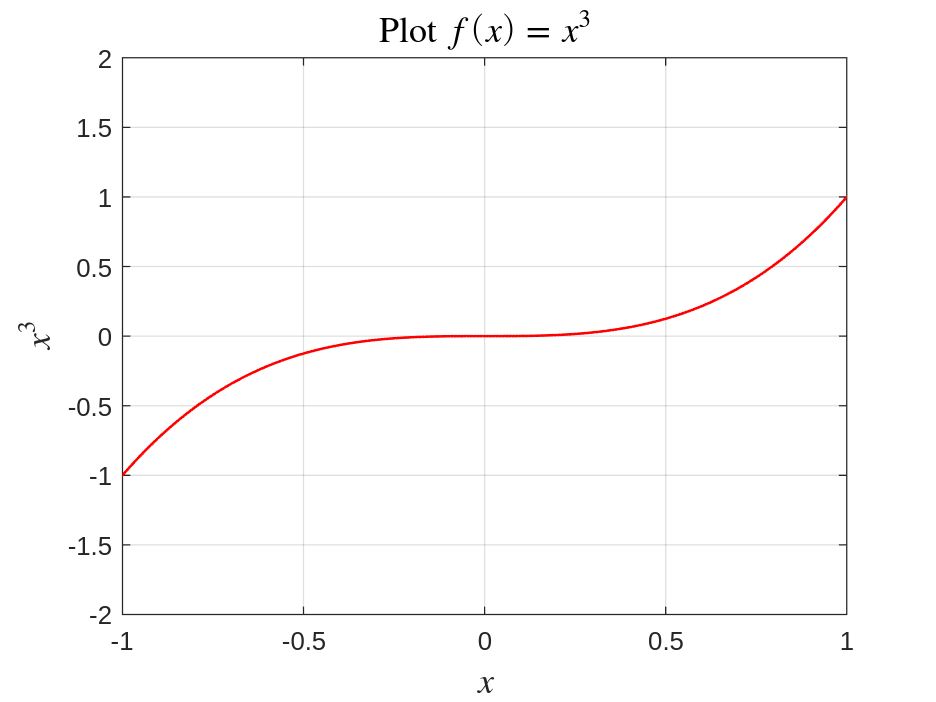

hold on

% turn on grid lines
grid on

% min and max delimiters for axes values to display
axis([-1 1 -2 2]);
% label the plot
xlabel('$x$','interpreter','latex','fontsize',14); 
ylabel('$x^3$','interpreter','latex','fontsize',14);
% the 'interpreter' and 'latex' choose a fancy interpreter for the latex
% language which makes the math show up pretty when enclosed in $

% give your plot a title
% the ... means the function input is also on the next line
title('Plot $f(x)=x^3$','interpreter','latex',...
    'fontsize',14);

## Example 4

Here is a simple example of how to implement a "for loop" to add the numbers between 1 and N. 

We also implement our algorithm as a function SumN at the bottom of this file. In this course, all algorithms will be written as a function so they can be reused easily. However, all functions in Matlab scripts must be placed at the end of the file, so scroll down to see the function SumN.

We will find the sum of the first 50 numbers

N=50;

% Initialize the sum variable as 0. We are going to add to this
sumN = 0;
for i=1:N
    
    % In each iteration we will add the new number i to our sum
    sumN = sumN+i;
end

% disp is the matlab function for printing
% num2str is the matlab function to take a number and make it into a
% "string" type which is for letters

% these strings can be combined by making an array of different strings
result = ['The sum of the first ' num2str(N) ' numbers is ' num2str(sumN)]

result = 'The sum of the first 50 numbers is 1275'

disp(result)

The sum of the first 50 numbers is 1275


Alternatively we can use the function at the bottom of the file

total=SumN(N);
result2 = ['The Sum is still ', num2str(total)]

result2 = 'The Sum is still 1275'

disp(result2)

The Sum is still 1275


## Example 5

Here is an example of computing the Taylor series of $sin(x)$ centered at 0 and evaluated at $x=1$ using a for loop with $N=20$ terms in the Taylor's series:


$$sin(x) \approx x - \frac{x^3}{3!} + \frac{x^5}{5!} - \ldots = \sum_{n=0}^{N} \frac{(-1)^{n}x^{2n+1}}{(2n+1)!}$$


% We want to use N=20 terms to evaluate the taylor series of sin centered at 0 at x=1
x = 1;
N = 20;

% Our answer will be stored in the variable my_sin1
my_sin1 = 0;

for n=0:N
    new_term = (-1)^n * (x^(2*n+1)) / factorial(2*n + 1);
    my_sin1 = my_sin1 + new_term;
end

% Our answer:
disp(my_sin1)

    0.8415



% Matlabs answer:
disp(sin(1))

    0.8415



% We can also take the code above and make it a function that needs inputs
% of x and N (included at the bottom of the file
disp(my_sin(1, 20))

    0.8415



## Functions

function [output] = SumN(input)
    % The names "input" and "output" are chosen to make it clear how this
    % function works. The names don't matter as long as they are consistent.
    N=input;
    sum=0;
    for i=1:N
        % In each iteration we will add the new number to our sum
        sum=sum+i;
    end
    output=sum;
end

function [answer] = my_sin(x, N)
    answer = 0;
    for n=0:N
        new_term = (-1)^n * (x^(2*n+1)) / factorial(2*n + 1);
        answer = answer + new_term;
    end
end